%тест1
n_1 = 3;
A = [[0.5 0.4 0.3];
    [0.02 0.3 0.1];
    [0.02 0.005 0.8]];
b_1 = [1 0 1]';
epsilon_1 = 1e-14;
x_1_si = SimpleIteration(A,b_1,epsilon_1);

Количество итераций:
    30



x_1_s = Seidel(A,b_1,epsilon_1);

Количество итераций: 
    16



x_1_si

x_1_si =    1.686243103755116
  -0.516106068695498
   1.211069585335469


x_1_s

x_1_s =    1.686243103755117
  -0.516106068695497
   1.211069585335469


%тест2
n_2 = 15;
H = hilb(n_2);
e = ones(n_2, 1);
b_2 = H*e;
epsilon_2 = 1e-10;
% x_2_si = SimpleIteration(H,b_2,epsilon_2);
x_2_s = Seidel(H,b_2,epsilon_2);

Количество итераций: 
     5492612



x_2_s

x_2_s =    0.999999634880114
   1.000017822889202
   0.999799805428987
   1.000833199866164
   0.998690478402895
   1.000175609886840
   1.000900648810904
   1.000360341038767
   0.999571908355897
   0.999275961769474


ans =    0.002366069726223


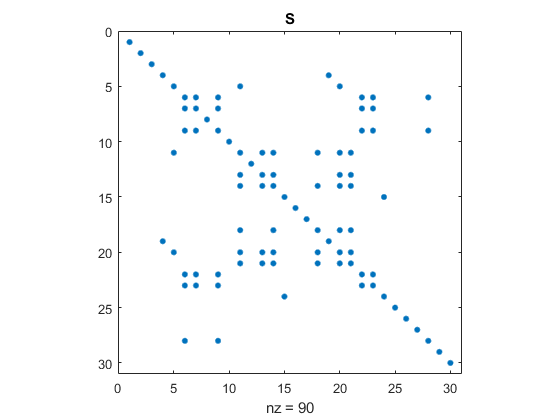

%тест3
n_3  = 30;
R = rand(n_3, 1, 'double');
S = sprandsym(n_3, 0.1, R);
spy(S), title('S');

epsilon_3 = 1e-14;
b_3 = ones(n_3, 1);
x_3_si = SimpleIteration(S, b_3, epsilon_3);

Количество итераций:
   980



x_3_s = Seidel(S, b_3, epsilon_3);

Количество итераций: 
   508



x_3_si

x_3_si = 	1.0e+02 *

   0.022722875902340
   0.018970193854135
   0.021861537666378
   0.030414980427232
   0.022521650181214
   0.045941283420160
  -0.429958172398231
   0.010441749272898
   0.243963481692914
   0.014790223518518


x_3_s

x_3_s = 	1.0e+02 *

   0.022722875902340
   0.018970193854135
   0.021861537666378
   0.030414980427232
   0.022521650181214
   0.045941283420160
  -0.429958172398232
   0.010441749272898
   0.243963481692915
   0.014790223518518
